
syms h(t) P(t) hj(t) Cs(t) t x1 x2 x3 x4 u1 u2 u3 u4  
% Sistema no lineal puro

%syms  h(t) P(t) hj(t) Cs(t) t u1 u2 u3 u4  % Obtener primero los valores del sistema en estado estacionario del otro .m

% x1 =  0.365;
% x2 = 6.1588;
% x3 = 5.53;
% x4 = 0.6;


sys = zeros(1,4);

flag =1;


% if flag ==1 % x(1) nivel
% 
%     A=4.35*(0.610-(2*(0.475-x1)/sqrt(3)));
%     V=(4.35*pi*0.355*0.355*0.5) + (4.35*asin((0.655-0.475)/0.355)*0.355*0.355)+ 4.35*((0.655-0.475)*0.610/2) + (0.475-x1)*((0.610 + (A/4.35))/2)*4.35;
% else
%     A=4.35*pi*0.71*cos(asin((0.655-x1)/0.355));
%     V=4.35*pi*0.355*0.355*0.2 + 4.35*asin((0.655-x1)/0.355)*0.355*0.355 + 4.35*(A*(0.655-x1)/(2*4.35));
% end
A = 2.1;
V= 1.7;

Vt = 1.8705;
Vs = 0.115;
T = 27;
Aa = 0.2670;
At = 0.3155;
c1= 30;
ae = (0.7854/39.375)/(39.375/2.9);
a1 = 1.31e-4;
k = 1.4;
g = 9.81;
rhow = 999.1; % Densidad del agua
rhoa = 1.293; % Densidad del aire
qi = 0.1;
atm = 10.34;
P0=atm;
friction = 0.13;
Nr = 4;
R = 287; % constante universal de los gases
Cds = 0.98;
L = 1.14;



angle = (3417/c1)*sqrt(x2/(x2+atm));
% if angle >= 90  % Comentar si los x son simbolicos
%     angle = 90;
% end 

GT = 32 + T*(9/5)+460;
qe = (((x2+atm)/atm)*(14.7)*sqrt(520/GT)*u2*sin(pi*angle/180))/(13.1*2.2*3600);
q1 = u1;
qs = 0.98*u3*sqrt(2*9.81*x3); % hj = x(3)
qo = 0.98*0.002*sqrt(2*9.81*x2); % P = x(2)

% if qo > 0.019
%     qo = 0.019;
% end

vb = qs/Aa;
vt = qs/At;
vj = qs/u3;

%%
Dh = diff(h(t),t);
sys11 = (1/A)*(q1-qs-qo);
sys1= Dh == (1/A)*(q1-qs-qo);
sys1 = vpa(sys1,3)

$$sys1 = \frac{\partial }{\partial t}h\left(t\right)=0.476\,u_{1}-0.467\,u_{3}\,\sqrt{19.6\,x_{3}}-9.33e-4\,\sqrt{19.6\,x_{2}}$$

DP = diff(P(t),t);
sys22= (k*P0/rhoa)*(((x2+atm)/P0)^((k-1)/k))*(1/V)*((qi-qe) +rhoa*A*(((x2+atm)/P0)^(1/k))*sys11);
sys2= DP == (k*P0/rhoa)*(((x2+atm)/P0)^((k-1)/k))*(1/V)*((qi-qe) +rhoa*A*(((x2+atm)/P0)^(1/k))*((1/A)*(q1-qs-qo))); % dP/dt
sys2 = vpa(sys2,3)

$$sys2 = \frac{\partial }{\partial t}P\left(t\right)=-6.59\,{\left(0.0967\,x_{2}+1.0\right)}^{2/7}\,\left(2.72\,{\left(0.0967\,x_{2}+1.0\right)}^{5/7}\,\left(0.467\,u_{3}\,\sqrt{19.6\,x_{3}}-0.476\,u_{1}+9.33e-4\,\sqrt{19.6\,x_{2}}\right)+9.45e-6\,u_{2}\,\sin\left(1.99\,\sqrt{\frac{x_{2}}{x_{2}+10.3}}\right)\,\left(1.42\,x_{2}+14.7\right)-0.1\right)$$


h0 = ((vb^2)/(2*g))*((1-(16^2/25^2))^2);

hi = x1+x2-h0;

ht = x3 - ((vt^2)/(2*g));

hf = (4*friction*Nr*(vt^2))/(2*g);

%% 
Dhj = diff(hj(t),t);
sys33 = (1/1.14)*sqrt(2*9.81*x3)*(hi-x3-hf);
sys3= Dhj == (1/1.14)*sqrt(2*9.81*x3)*(hi-x3-hf);
sys3 = vpa(sys3,3)

$$sys3 = \frac{\partial }{\partial t}\mathrm{hj}\left(t\right)=0.877\,\sqrt{19.6\,x_{3}}\,\left(-24.8\,x_{3}\,{u_{3}}^{2}+x_{1}+x_{2}-1.0\,x_{3}\right)$$

DCs = diff(Cs(t),t);
sys4 = DCs == q1*(u4-x4)/(Vs);
sys44 =  q1*(u4-x4)/(Vs);
sys4 = vpa(sys4,3)

$$sys4 = \frac{\partial }{\partial t}\mathrm{Cs}\left(t\right)=8.7\,u_{1}\,\left(u_{4}-1.0\,x_{4}\right)$$

Ecuaciones = [sys1 sys2 sys3 sys4]';
Ecuaciones = vpa(Ecuaciones,3)

$$Ecuaciones = \begin{array}{l} \left(\begin{array}{c} \bar{\frac{\partial }{\partial t}h\left(t\right)=0.476\,u_{1}-\sigma_{1}-\sigma_{2}}\\ \bar{\frac{\partial }{\partial t}P\left(t\right)=-6.59\,{\left(0.0967\,x_{2}+1.0\right)}^{2/7}\,\left(2.72\,{\left(0.0967\,x_{2}+1.0\right)}^{5/7}\,\left(\sigma_{1}-0.476\,u_{1}+\sigma_{2}\right)+9.45e-6\,u_{2}\,\sin\left(1.99\,\sqrt{\frac{x_{2}}{x_{2}+10.3}}\right)\,\left(1.42\,x_{2}+14.7\right)-0.1\right)}\\ \bar{\frac{\partial }{\partial t}\mathrm{hj}\left(t\right)=0.877\,\sqrt{19.6\,x_{3}}\,\left(-24.8\,x_{3}\,{u_{3}}^{2}+x_{1}+x_{2}-1.0\,x_{3}\right)}\\ \bar{\frac{\partial }{\partial t}\mathrm{Cs}\left(t\right)=8.7\,u_{1}\,\left(u_{4}-1.0\,x_{4}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.467\,u_{3}\,\sqrt{19.6\,x_{3}}\\ \sigma_{2}=9.33e-4\,\sqrt{19.6\,x_{2}} \end{array}$$

## Obtencion de los Jacobianos del Sistema


% Puntos del sistema en estado estacionario


% Linealizacion del sistema
A = jacobian([sys11;sys22;sys33;sys44],[x1;x2;x3;x4]);
B = jacobian([sys11;sys22;sys33;sys44],[u1,u2,u3,u4]);
C = eye(4);
D = zeros(4);

x1 = 0.365;
x2 = 6.44;
x3 = 5.53;
x4 = 0.6;
u1 = 0.8422;
u2 = 483.5783;
u3 = 0.0804;
u4 = 0.6;

A = eval(A)

A =                          0     -0.000814541749003429       -0.0353361939451838                         0
                         0       -0.0869733326353881         -1.02543971949208                         0
          9.13707554880048          9.13707554880048         -10.2777706228122                         0
                         0                         0                         0         -7.32347826086956


B =eval(B)

B =          0.476190476190476                         0         -4.86092419196185                         0
          13.8188235294118      -0.00160822644343787         -141.061732556996                         0
                         0                         0         -201.209443145023                         0
                         0                         0                         0          7.32347826086956


C

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D

D =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


## Funciones de Transferencia - Variables de estado


syms s U X Y x_s u1_s u1(s) u2(s) u3(s) u4(s)


Fun_trans = C*inv(s*eye(4)-A)*B+D;
%Fun_trans = C*(s*eye(4)-A)\B+D; % Analizar la sugerencia de matlab
Fun_trans = simplify(Fun_trans);
Fun_trans = vpa(Fun_trans,3)

$$Fun\_trans = \begin{array}{l} \left(\begin{array}{cccc} \frac{0.00717\,\left(1.31e+37\,s^{2}+1.35e+38\,s+8.53e+36\right)}{\sigma_{1}} & \frac{0.103\,\left(2.51e+30\,s+1.02e+33\right)}{\sigma_{1}} & -\frac{1.62e-27\,\left(347.0\,\left(9.69e+46\,s+2.04e+44\right)\,\sigma_{3}-3.42e+17\,s\,\sigma_{6}\,\sigma_{3}\right)}{\sigma_{5}} & 0\\ \frac{1.21e+13\,\left(2.25e+23\,s^{2}+2.31e+24\,s-2.97e+6\right)}{\sigma_{1}} & -\frac{5.79e+13\,\left(5.48e+18\,s^{2}+5.63e+19\,s+1.77e+18\right)}{\sigma_{1}} & -\frac{0.5\,\left(347.0\,\left(5.51e+33\,s+1.16e+31\right)\,\sigma_{4}-1.95e+4\,s\,\sigma_{6}\,\sigma_{4}\right)}{\sigma_{5}} & 0\\ \frac{3.5e+14\,\left(7.35e+22\,s+1.55e+20\right)}{\sigma_{1}} & -\frac{5.03e+15\,\left(5.76e+17\,s-4.7e+14\right)}{\sigma_{1}} & -\frac{0.5\,\left(347.0\,\left(5.51e+33\,s+1.16e+31\right)\,\sigma_{2}-1.95e+4\,s\,\sigma_{6}\,\sigma_{2}\right)}{\sigma_{5}} & 0\\ 0 & 0 & 0 & \frac{4210.0}{575.0\,s+4210.0} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=1.97e+35\,s^{3}+2.05e+36\,s^{2}+2.09e+36\,s+4.03e+33\\ \sigma_{2}=3.97e+37\,s^{2}+2.67e+38\,s+5.55e+35\\ \sigma_{3}=1.69e+49\,s^{2}+1.5e+50\,s+9.42e+48\\ \sigma_{4}=2.78e+37\,s^{2}+2.45e+38\,s+6.24e+19\\ \sigma_{5}=6.03e+4\,{\left(5.51e+33\,s+1.16e+31\right)}^{2}-1.89e+8\,s^{2}\,{\sigma_{6}}^{2}\\ \sigma_{6}=1.01e+31\,s^{2}+1.05e+32\,s+9.07e+30 \end{array}$$

h_s = Fun_trans(1,1)*u1(s)+Fun_trans(1,2)*u2(s)+Fun_trans(1,3)*u3(s)+Fun_trans(1,4)*u4(s);
h_s = simplify(h_s);
h_s = vpa(h_s,3)

$$h\_s = \begin{array}{l} \frac{0.00717\,u_{1}\left(s\right)\,\left(1.31e+37\,s^{2}+1.35e+38\,s+8.53e+36\right)}{\sigma_{1}}-\frac{1.62e-27\,u_{3}\left(s\right)\,\left(347.0\,\left(9.69e+46\,s+2.04e+44\right)\,\sigma_{3}-3.42e+17\,s\,\sigma_{2}\,\sigma_{3}\right)}{6.03e+4\,{\left(5.51e+33\,s+1.16e+31\right)}^{2}-1.89e+8\,s^{2}\,{\sigma_{2}}^{2}}+\frac{0.103\,u_{2}\left(s\right)\,\left(2.51e+30\,s+1.02e+33\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=1.97e+35\,s^{3}+2.05e+36\,s^{2}+2.09e+36\,s+4.03e+33\\ \sigma_{2}=1.01e+31\,s^{2}+1.05e+32\,s+9.07e+30\\ \sigma_{3}=1.69e+49\,s^{2}+1.5e+50\,s+9.42e+48 \end{array}$$


P_s = Fun_trans(2,1)*u1(s)+Fun_trans(2,2)*u2(s)+Fun_trans(2,3)*u3(s)+Fun_trans(2,4)*u4(s);
P_s = vpa(P_s,3)

$$P\_s = \begin{array}{l} \frac{1.21e+13\,u_{1}\left(s\right)\,\left(2.25e+23\,s^{2}+2.31e+24\,s-2.97e+6\right)}{\sigma_{1}}-\frac{5.79e+13\,u_{2}\left(s\right)\,\left(5.48e+18\,s^{2}+5.63e+19\,s+1.77e+18\right)}{\sigma_{1}}-\frac{0.5\,u_{3}\left(s\right)\,\left(347.0\,\left(5.51e+33\,s+1.16e+31\right)\,\sigma_{3}-1.95e+4\,s\,\sigma_{2}\,\sigma_{3}\right)}{6.03e+4\,{\left(5.51e+33\,s+1.16e+31\right)}^{2}-1.89e+8\,s^{2}\,{\sigma_{2}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=1.97e+35\,s^{3}+2.05e+36\,s^{2}+2.09e+36\,s+4.03e+33\\ \sigma_{2}=1.01e+31\,s^{2}+1.05e+32\,s+9.07e+30\\ \sigma_{3}=2.78e+37\,s^{2}+2.45e+38\,s+6.24e+19 \end{array}$$

hj_s = Fun_trans(3,1)*u1(s)+Fun_trans(3,2)*u2(s)+Fun_trans(3,3)*u3(s)+Fun_trans(3,4)*u4(s);
hj_s = simplify(hj_s);
disp(vpa(hj_s, 3));

$$\begin{array}{l} \frac{3.5e+14\,u_{1}\left(s\right)\,\left(7.35e+22\,s+1.55e+20\right)}{\sigma_{1}}-\frac{5.03e+15\,u_{2}\left(s\right)\,\left(5.76e+17\,s-4.7e+14\right)}{\sigma_{1}}-\frac{0.5\,u_{3}\left(s\right)\,\left(347.0\,\left(5.51e+33\,s+1.16e+31\right)\,\sigma_{3}-1.95e+4\,s\,\sigma_{2}\,\sigma_{3}\right)}{6.03e+4\,{\left(5.51e+33\,s+1.16e+31\right)}^{2}-1.89e+8\,s^{2}\,{\sigma_{2}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=1.97e+35\,s^{3}+2.05e+36\,s^{2}+2.09e+36\,s+4.03e+33\\ \sigma_{2}=1.01e+31\,s^{2}+1.05e+32\,s+9.07e+30\\ \sigma_{3}=3.97e+37\,s^{2}+2.67e+38\,s+5.55e+35 \end{array}$$



Cs_s = Fun_trans(4,1)*u1(s)+Fun_trans(4,2)*u2(s)+Fun_trans(4,3)*u3(s)+Fun_trans(4,4)*u4(s);
Cs_s = vpa(Cs_s,3)

$$Cs\_s = \frac{4210.0\,u_{4}\left(s\right)}{575.0\,s+4210.0}$$

## Funcion de Transferencia


H_s = [h_s P_s hj_s Cs_s]';
%H_s = vpa(H_s,3)
H_s = simplify(H_s);
disp(vpa(H_s, 3));

## Constante de tiempo del sistema

%% Crear el sistema de espacio de estados
Espacio_Estados = ss(A, B, C, D);


%% Simular la respuesta al escalón
t = 0:0.01:10; % Define el tiempo de simulación
[Y, T] = step(Espacio_Estados, t);


%% Obtener la información de la respuesta al escalón
Resp_info = arrayfun(@(i) stepinfo(Y(:,i,:), T), 1:4, 'UniformOutput', false);

%% Mostrar la información de la respuesta al escalón
for i = 1:4
    fprintf('Salida %d:\n', i);
    fprintf('  Tiempo de subida: %f segundos\n', Resp_info{i}.RiseTime);
    fprintf('  Tiempo de asentamiento: %f segundos\n', Resp_info{i}.SettlingTime);
    fprintf('  Tiempo pico: %f segundos\n', Resp_info{i}.PeakTime);
    fprintf('  Máximo sobrepaso: %f %%\n\n', Resp_info{i}.Overshoot);
end

Salida 1:


  Tiempo de subida: 7.276362 segundos
  Tiempo de subida: 7.352534 segundos
  Tiempo de subida: 7.287441 segundos
  Tiempo de subida: 0.000000 segundos


  Tiempo de asentamiento: 9.484932 segundos
  Tiempo de asentamiento: 9.818026 segundos
  Tiempo de asentamiento: 9.484591 segundos
  Tiempo de asentamiento: 0.000000 segundos


  Tiempo pico: 10.000000 segundos
  Tiempo pico: 10.000000 segundos
  Tiempo pico: 10.000000 segundos
  Tiempo pico: 0.000000 segundos


  Máximo sobrepaso: 0.000000 %

  Máximo sobrepaso: 0.000000 %

  Máximo sobrepaso: 0.000000 %

  Máximo sobrepaso: Inf %



Salida 2:


  Tiempo de subida: 1.812963 segundos
  Tiempo de subida: 5.579712 segundos
  Tiempo de subida: 1.804141 segundos
  Tiempo de subida: 0.000000 segundos


  Tiempo de asentamiento: 2.987363 segundos
  Tiempo de asentamiento: 9.129144 segundos
  Tiempo de asentamiento: 2.968049 segundos
  Tiempo de asentamiento: 0.000000 segundos


  Tiempo pico: 5.590000 segundos
  Tiempo pico: 10.000000 segundos
  Tiempo pico: 5.570000 segundos
  Tiempo pico: 0.000000 segundos


  Máximo sobrepaso: 0.687840 %

  Máximo sobrepaso: 0.000000 %

  Máximo sobrepaso: 0.691396 %

  Máximo sobrepaso: Inf %



Salida 3:


  Tiempo de subida: 1.951919 segundos
  Tiempo de subida: 1.792064 segundos
  Tiempo de subida: 1.898304 segundos
  Tiempo de subida: 0.000000 segundos


  Tiempo de asentamiento: 3.575745 segundos
  Tiempo de asentamiento: 2.954694 segundos
  Tiempo de asentamiento: 3.406016 segundos
  Tiempo de asentamiento: 0.000000 segundos


  Tiempo pico: 10.000000 segundos
  Tiempo pico: 5.390000 segundos
  Tiempo pico: 10.000000 segundos
  Tiempo pico: 0.000000 segundos


  Máximo sobrepaso: 0.000000 %

  Máximo sobrepaso: 1.040984 %

  Máximo sobrepaso: 0.000000 %

  Máximo sobrepaso: Inf %



Salida 4:


  Tiempo de subida: 0.000000 segundos
  Tiempo de subida: 0.000000 segundos
  Tiempo de subida: 0.000000 segundos
  Tiempo de subida: 0.300025 segundos


  Tiempo de asentamiento: 0.000000 segundos
  Tiempo de asentamiento: 0.000000 segundos
  Tiempo de asentamiento: 0.000000 segundos
  Tiempo de asentamiento: 0.534265 segundos


  Tiempo pico: 0.000000 segundos
  Tiempo pico: 0.000000 segundos
  Tiempo pico: 0.000000 segundos
  Tiempo pico: 4.740000 segundos


  Máximo sobrepaso: Inf %

  Máximo sobrepaso: Inf %

  Máximo sobrepaso: Inf %

  Máximo sobrepaso: 0.000000 %



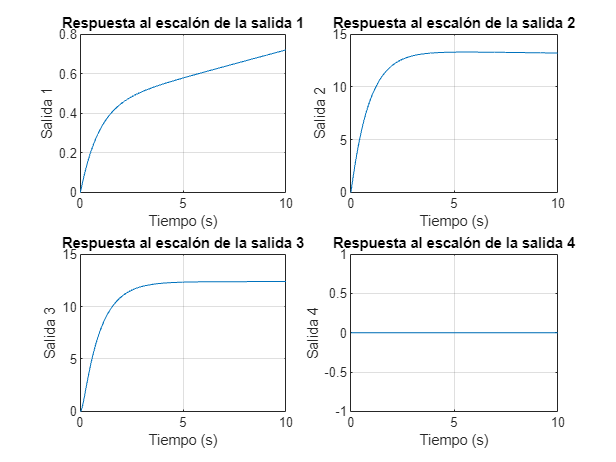


%% Graficar la respuesta al escalón
figure;
for i = 1:4
    subplot(2, 2, i);
    plot(T, Y(:, i));
    title(['Respuesta al escalón de la salida ' num2str(i)]);
    xlabel('Tiempo (s)');
    ylabel(['Salida ' num2str(i)]);
    grid on;
end

## Modelo ARMA Multivariable